clear
cd('C:\Users\Administrator\Desktop\Scene-Depth-Ordering\hazy_images\')
[fName,pName]=uigetfile({'*.png'},'Open');
if fName
   I=imread([pName fName]); 
end

tic
dehazed = dehaze_sdo(I);
toc

时间已过 0.336584 秒。


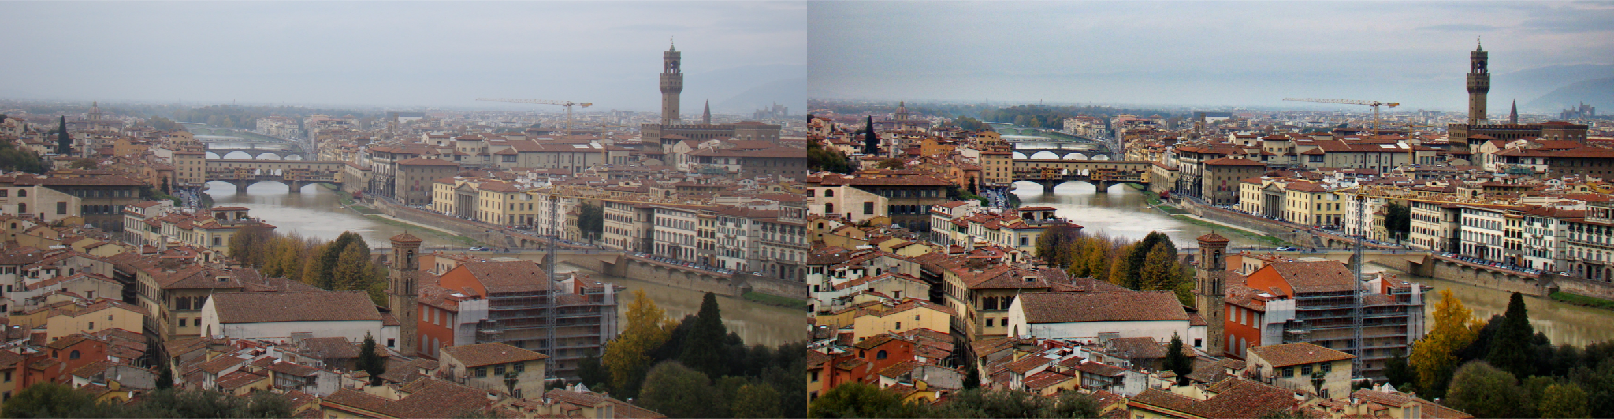


imshow([I,dehazed*255],'Border','tight')